This file is to compare the current version of TM30 outputs from my function with those of Tucker Downs' results.

Note that he does not linearly interpolate the11664-1 metrics.

He also probably has a slightly different CCT calculation

## Load The 318 Example SPDs

clear
filepath = fileparts(which('compareAndVerifyTm30'));
load(filepath + "\TM30_ExampleSPDs.mat");

## Load Tucker Downs' results

load( string( filepath + "\Full_TM30_Data.mat" ) );
% Full_TM30_Data.rf = Full_TM30_Data.Rf;

## Create my results

for i = 1:width(A_ExampleSPDs)
    Stemp.s = A_ExampleSPDs(:,i);
    MySpd(i) = spdToTM30(Stemp);
end


## Plot Absolute Errors

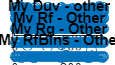

Tm30AbsErrorFig = figure;

sp1_CCT     = subplot(5,1,1); hold on; title("My CCT - Other");
cctDiffPlot = plot([MySpd(1:length(MySpd)).cct] - [Full_TM30_Data(1:length(MySpd)).cct],'-o');

sp2_Duv     = subplot(5,1,2); hold on; title("My Duv - other");
duvDiffPlot = plot([MySpd(1:length(MySpd)).duv] - [Full_TM30_Data(1:length(MySpd)).duv],'-o');

sp3_Rf      = subplot(5,1,3); hold on; title("My Rf - Other");
rfDiffPlot  = plot([MySpd(1:length(MySpd)).rf] - [Full_TM30_Data(1:length(MySpd)).Rf],'-o');

sp4_Rg      = subplot(5,1,4);  hold on; title("My Rg - Other");
rgDiffPlot  = plot([MySpd(1:length(MySpd)).rg] - [Full_TM30_Data(1:length(MySpd)).Rg],'-o');

sp5_Rg      = subplot(5,1,5);  hold on; title("Sum of My RfBins - Other RfBins");
Full_TM30_Bins = [Full_TM30_Data.Bins];

rfBinDiffPlot  = plot(1:length(Full_TM30_Bins), sum([MySpd.rfBins]-[Full_TM30_Bins.Rf]),'-o');

set(gcf,'Position', get(0,'ScreenSize')./2);

## Plot Percent Errors

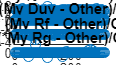


Tm30PercErrorFig = figure;

sp1_CCT = subplot(4,1,1); hold on; title("100* (My CCT - Other)/Other");
cctDiffPlot = plot( 100*( [MySpd.cct] - [Full_TM30_Data.cct]  )./[Full_TM30_Data.cct],'-o');

sp2_Duv = subplot(4,1,2); hold on; title("100* (My Duv - Other)/Other");
duvDiffPlot = plot( 100*( [MySpd.duv] - [Full_TM30_Data.duv] )./[Full_TM30_Data.duv] , '-o');

sp3_Rf = subplot(4,1,3); hold on; title("100* (My Rf - Other)/Other");
rfDiffPlot  = plot( 100*( [MySpd.rf] - [Full_TM30_Data.Rf] )./[Full_TM30_Data.Rf] , '-o');

sp4_Rg = subplot(4,1,4);  hold on; title("100 (*My Rg - Other)/Other");
rgDiffPlot  = plot( 100*( [MySpd.rg] - [Full_TM30_Data.Rg] )./[Full_TM30_Data.Rg] , '-o');
set(gcf,'Position', get(0,'ScreenSize')./2);

## Save

% theDate = split(datestr(now));
% 
% 
% saveas(Tm30AbsErrorFig, strcat("TM30 Absolute Error" +" " + theDate{1} +".png"));
% saveas(Tm30PercErrorFig, strcat("TM30 Percent Error" +" " + theDate{1} +".png"));
% 

% 
% 
% MySpd(56).csBins
% sum([MySpd(56).csBins])
% Full_TM30_Data(56).Bins.Rcs'
% sum([Full_TM30_Data(56).Bins.Rcs'])
% 
% 
% MySpd(56).hsBins
% sum([MySpd(56).hsBins])
% Full_TM30_Data(56).Bins.Rhs'
% sum([Full_TM30_Data(56).Bins.Rhs'])
% 
% 